# Microring Resonators as analog processors - Photonic Project 2026

## Microring resonators solving first-order liner ordinary differential equation

A first-order linear ODE can be represented as: 


$$\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}+\textrm{ky}\left(t\right)=x\left(t\right)$$


By applying the Fourier transform, we can write the equation in the frequency domain:


$$H\left(\omega \right)=\frac{1}{k+j\omega }$$


The signal coming out from the drop port of a MRR, is described by the following equation:


$$H_{\textrm{dr}} \left(\omega \right)=\frac{k}{k+j\left(\omega -\omega_0 \right)}$$


As we can see, these two equations are strictly correlated.

The signal coming out from the drop port of a properly designed MRR, if scaled by $\frac{1}{k}$, it can solve a first-order linear ODE with constant-coefficient valued as k.

In our code, we implemented a class called `mrr.m`, which models a microring resonator (that uses a drop port as its output port) inside our matlab scripts.

Let's suppose, from a current driven RC circuit,  we want to find the equation that describes the voltage between the capacitance and the ground. A RC circuit is described by the following differential equation:


$$\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}=\frac{1}{C}\left\lbrack -\frac{1}{R}y\left(t\right)+x\left(t\right)\right\rbrack$$


Where:

- $y\left(t\right)$ is the voltage of the capacitance

- $x\left(t\right)$ is the input signal (current)

- $C$ is the capacitance

- $R$ is the resistance

For simplicity, we give to ***C*** and ***R*** two made up values:

- 
$$C=1\textrm{nF}$$


- 
$$R=16m\Omega$$


By these data, we can model a MRR.

Assumptions:

- No chromatic dispersion: $n_g =n_{\textrm{eff}}$

- Ideal case: $\alpha =0$ (no power line losses)

- 
$$y\left(0\right)=0$$


A=1e9;  %time scaling parameter  [nano 10^9]

k = 62.5; % ns-1
R=30e-6;  %radius of the MRR [m]
neff=2.4;   %effective index of the MRR waveguide (SOI)
alpha = 0; % attenuation coefficient

% creating the microring resonator
MRR = mrr(R, neff, k, A, alpha);

### Consideration on input bandwidth signal

We will consider the input signal $x\left(t\right)$ as a Gaussian impulse, described by the equation:


$$x\left(t\right)=\exp \left(-\log \left(2\right)*{\left(\frac{2t}{\textrm{FWHM}}\right)}^2 \right)$$


Choosing the value of the **FWHM **is not trivial, since different values can heavily influence the output of the previously built MRR.

The FWHM controls the bandwidth of a Gaussian impulse:


$$B_{\textrm{in}} \propto\frac{1}{\textrm{FWHM}}$$


Now we introduce the definition of cavity lifetime:

$\tau_c =\frac{1}{k}$ (for ODE)

For our MRR, this value is $\tau_c =16\;\textrm{ps}$

By comparing the magnitude of the cavity lifetime and the **FWHM** we can understand which behaviour our MRR will have.

#### MRR as an Integrator - FWHM << cavity lifetime

If FWHM's order of magnitude is lower than the cavity lifetime, then our MRR can solve integrals of the input function.

From the equation that models the output of the drop port: 


$$$H_{\mathrm{dr}} \left(\omega \right)=\frac{k}{k+j\left(\omega -\omega_0 \right)}$$$


If the bandwidth of the input signal is several order of magnitude bigger than the inverse of the cavity lifetime, the k parameter at the denominator becomes negligible:


$$H_{\textrm{dr}} \left(\omega \right)\cong \frac{k}{j\left(\omega -\omega_0 \right)}$$


Scaling the output, the equation that solves becomes: 


$$\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}=x\left(t\right)\to y\left(t\right)=\int x\left(t\right)\;\textrm{dt}$$


So the solution of the equation, is the integral of the input.

#### MRR as an Input scaler - FWHM >> cavity lifetime

If FWHM's order of magnitude is greater than the cavity lifetime, then our MRR will return a weighted replica (by $\frac{1}{k}$) of the input function.

From the equation that models the output of the drop port: 


$$$H_{\mathrm{dr}} \left(\omega \right)=\frac{k}{k+j\left(\omega -\omega_0 \right)}$$$


If the bandwidth of the input signal is several order of magnitude smaller than the inverse of the cavity lifetime, the k parameter at the imaginary part of the denominator becomes negligible:


$$H_{\textrm{dr}} \left(\omega \right)\cong 1$$


The solution will be:


$$k\cdot y\left(t\right)=x\left(t\right)\to y\left(t\right)=\frac{1}{k}\cdot x\left(t\right)$$


#### MRR as an first-order linear ODE solver - FWHM with same order of magnitude  as cavity lifetime

If FWHM's order of magnitude is the same as the cavity lifetime, then our MRR can solve first-order linear ODE with a constant-coefficient k.

As we mentioned in the previous chapters, a first-order linear ODE is described by the following equation: 


$$\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}+k\cdot y\left(t\right)=x\left(t\right)$$


After having applied the Fourier Transform, we obtain:


$$H\left(\omega \right)=\frac{1}{k+j\omega }$$


Which is equal to the equation at the drop port of a correctly built MRR:


$$H_{\textrm{dr}} \left(\omega \right)=\frac{k}{k+j\omega }=k\cdot H\left(\omega \right)$$


#### MATLAB script to understand the analysis on input bandwidth

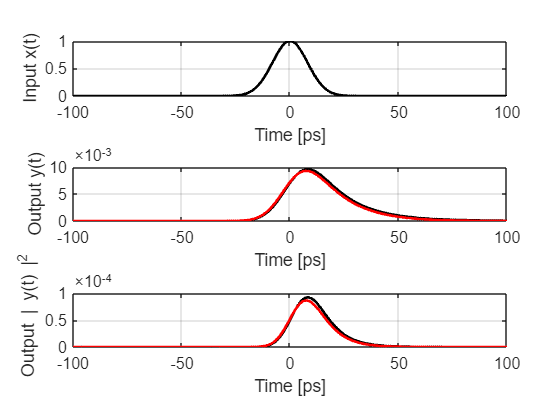

k_eq = 62.5; % ns^-1

A = 1e9;  %time scaling parameter  [nano 10^9]

% Input signal x(t)

% ODE SOLVER: exp = 3
% INTEGRATOR: exp = 4
% SCALER: exp = 0

% move the slider to one of the values reported above
exp = 3;
mrr_function = 10^exp;

A_time =  A * mrr_function;
FWHM = 19.07 / mrr_function; 

x = Model_utils.super_gaussian_function(FWHM,A);

% Definition of the ODE
odefun = Model_utils.first_order_ode(A, k_eq, x);

% Initial condition
y0 = 0;

N = 1e5;
% Time span
interval = 100/A_time;
tspan = linspace(-interval , interval, N);

% Solve using ode45
[t, y] = ode45(odefun, tspan, y0);


fsr = MRR.FSR(MRR.neff);

n_fsr_range = 1; 
dt_max = 1 / (2 * n_fsr_range * fsr);

dt = (max(t) - min(t)) / (N - 1);
if dt > dt_max
    N = ceil((max(t) - min(t)) / dt_max) + 1;
    time = linspace(min(t), max(t), N);
    dt = time(2) - time(1);
else
    time = linspace(min(t), max(t), N);
end

in_ring = x(time);
IN_ring=fftshift(fft(in_ring));

Df=linspace(-1/(2*dt),1/(2*dt),N);


%% computing output

delta_f = 0; % no phase detuning in this part
[H_drop, H_drop_norm] = MRR.h_drop_f(Df, delta_f);


if mod(delta_f, fsr) == 0
    tras = delta_f;
else
    tras = 0;
end

H_ODE = MRR.h_ode(Df, tras);

Out_ring=IN_ring.*H_drop;
Out_ODE=IN_ring.*H_ODE;

Out_ring_plot = IN_ring.*H_drop_norm;

out_ring=real(ifft(ifftshift(Out_ring)));
out_ode=real(ifft(ifftshift(Out_ODE)));

out_ring_plot = real(ifft(ifftshift(Out_ring_plot)));


%% generate plots
t_min=-1;t_max=20;

utils = graph_drawer(t_min, t_max, time);

figure(1)
utils.input_output_power(in_ring, out_ring_plot,t ,y, A_time);

clf(figure(1));
drawnow;

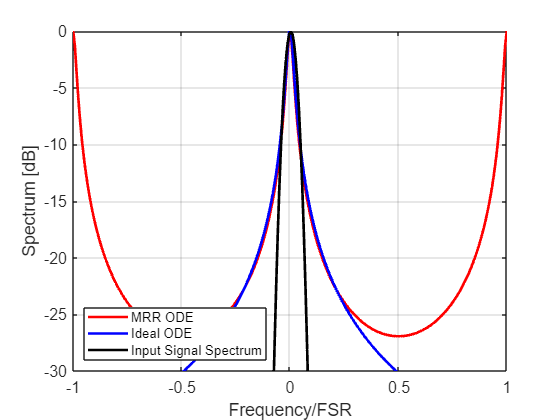

figure(2)
axes;
graph_drawer.spectrum_fsr(Df, H_drop, H_ODE, IN_ring, fsr, n_fsr_range);

drawnow;
clf(figure(2));

### Considerations on Root Mean Square Error & Power consumed

% comuting rmse
rmse = Model_utils.computing_rmse(time, t, out_ring_plot, y, N);

% computing power consumed [Watt, dB]
[p, db] = MRR.power_loss(in_ring, out_ring, dt);

fprintf("RMSE = %g\n", rmse);

RMSE = 0.00020253


fprintf("Power consumed in Watt = %g W\n", p);

Power consumed in Watt = -7.05865e-12 W


fprintf("Power consumed in dB = %g dB\n", db);

Power consumed in dB = -2.93931 dB


### Changing equation's parameter

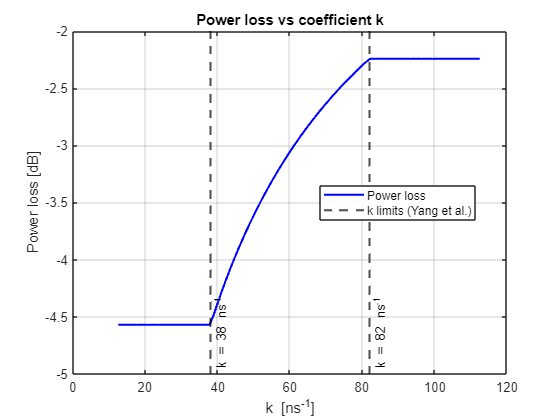

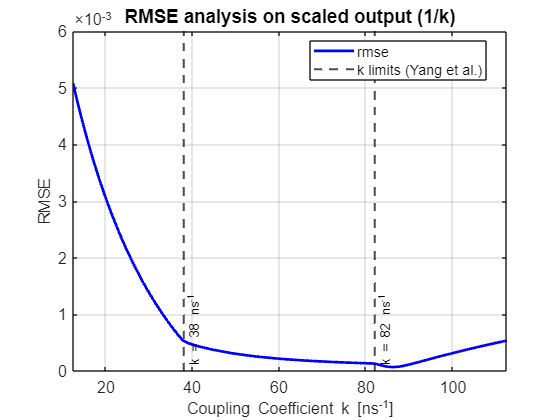

close all
clear all 
clc

k_eq = 62.5; % ns^-1
k = 62.5;  % ns^-1
A=1e9;  %time scaling parameter  [nano 10^9]
A_time = A * 1e3;
% Input signal x(t)

FWHM = 19.07 * 1e-3; 

% Input signal x(t)

x = Model_utils.super_gaussian_function(FWHM, A);

% Definition of the ODE
odefun = Model_utils.first_order_ode(A, k_eq, x);

% Initial condition
y0 = 0;

% Time span
N=1e5;
interval = 100/A_time;
tspan = linspace(-interval , interval, N);

% Solve using ode45
[t, y] = ode45(odefun, tspan, y0);


%% creatinng MRR
R=30e-6;  %radius of the MRR
neff=2.4;   %effective index of the MRR waveguide
MRR = mrr(R, neff, k, A, 0);

%% ANALYSIS on CHANGING K_eq
% MRR extra parameters
k_perfect = k_eq; % k parameter of MRR to solve perfectly the ODE
is_tunable = true; % is the MRR tunable


%% Computing input

time=linspace(min(t),max(t),N);
dt=time(2)-time(1);
in_ring = x(time);
IN_ring=fftshift(fft(in_ring));

Df=linspace(-1/(2*dt),1/(2*dt),N);



            
N = 100;

k_values = linspace(max(k_perfect-50, eps), k_perfect + 50, N);

% preparing output vectors
% preparing power output vector
p_out_db = zeros(1, N);
% preparing rmse values
%rmse_values = zeros(1,N);
rmse_values_scaled = zeros(1,N);

% parameter useful for ODE
y0 = 0;

% for loop changing k values
for i = 1 : length(k_values)

    if is_tunable
        if k_values(i) >= min(mrr.k_Yang) && k_values(i) <= max(mrr.k_Yang) 
            MRR.tuning_k(k_values(i));
        elseif k_values(i) <= min(mrr.k_Yang)
            MRR.tuning_k(min(mrr.k_Yang));
        elseif k_values(i) >= max(mrr.k_Yang)
            MRR.tuning_k(max(mrr.k_Yang));
        else
            error("Invalid k value reached")
        end
    end

    
    % suppose no phase detuning
    
    odefun = Model_utils.first_order_ode(A, k_values(i), x);
    [H_out, H_out_norm] = MRR.h_drop_f(Df, 0);
    
    
    sol = ode45(odefun, tspan, y0);
    

    Out_ring=IN_ring.*H_out;
    Out_ring_norm = IN_ring.*H_out_norm;
    
    out_ring=real(ifft(fftshift(Out_ring)));
    out_ring_norm = real(ifft(fftshift(Out_ring_norm)));
    
    [~, p_out_db(i)] = MRR.power_loss(in_ring, out_ring, dt);
    
    y = deval(sol, time); % making y length == out_ring_norm
    rmse_values_scaled(i) = sqrt(mean(abs(out_ring_norm - y).^2));
    %rmse_values(i) = sqrt(mean(abs(out_ring - y).^2));
end

% plotting results
if is_tunable 
    graph_drawer.plot_power_vs_k(k_values, p_out_db)
    graph_drawer.plot_rmse_analysis(k_values, rmse_values_scaled)
else
    graph_drawer.plot_power_vs_k(k_values, p_out_db, k_perfect)
    graph_drawer.plot_rmse_analysis(k_values, rmse_values_scaled, k_perfect)
end

### Phase detuning

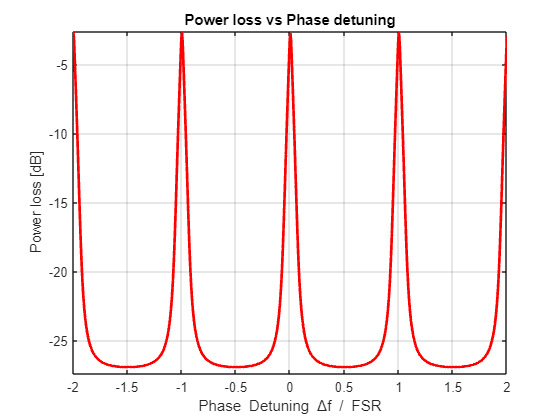

close all
clear all 
clc

k_eq = 62.5; % ns^-1
k = 62.5;  % ns^-1
A=1e9;  %time scaling parameter  [nano 10^9]
A_time = A * 1e3;

% ODE SOLVER: k = Bs -> A_time = A * 1e3;
% FWHM = 19.07 * 1e-3;
FWHM = 19.07 * 1e-3; 

% Input signal x(t)
%x = Model_utils.sin_function(A);
x = Model_utils.super_gaussian_function(FWHM, A);
%x = Model_utils.arbitrary_signal(A);

% Definition of the ODE
odefun = Model_utils.first_order_ode(A, k_eq, x);

% Initial condition
y0 = 0;

% Time span
N=1e5;
interval = 100/A_time;
tspan = linspace(-interval , interval, N);

% Solve using ode45
[t, y] = ode45(odefun, tspan, y0);


%% creatinng MRR
R=30e-6;  %radius of the MRR
neff=2.4;   %effective index of the MRR waveguide
MRR = mrr(R, neff, k, A, 0);

%% Computing input

time=linspace(min(t),max(t),N);
dt=time(2)-time(1);
in_ring = x(time);
IN_ring=fftshift(fft(in_ring));

Df=linspace(-1/(2*dt),1/(2*dt),N);

fsr = MRR.FSR(neff); % no chromatic dispersion assumption
b3db = MRR.B3dB(fsr);
N_det = 1e3;
delta_f_array = linspace(-2 * fsr, 2 * fsr, N_det);

% helpful vectors
phase_detuning = zeros(1, N_det);

% output vectors
P_out  = zeros(1, N_det);
P_in = zeros(1, N_det);
P_lost_db = zeros(1, N_det);

rmse_det = zeros(1, N_det);

for i = 1:N_det
    delta_f = delta_f_array(i);

    [H_drop, H_drop_norm] = MRR.h_drop_f(Df, delta_f);

    Out_ring = IN_ring .* H_drop;
    out_ring = real(ifft(ifftshift(Out_ring)));
    
    Out_ring_norm = IN_ring .* H_drop_norm;
    out_ring_norm = real(ifft(ifftshift(Out_ring_norm)));

    P_in(i) = MRR.power(in_ring, dt);
    P_out(i) = MRR.power(out_ring, dt);
    
    [~, P_lost_db(i)] = MRR.power_loss(in_ring, out_ring, dt);

    rmse_det(i) = Model_utils.computing_rmse(time, t, out_ring_norm, y, N);
    
end

delta_f_array = delta_f_array / fsr;


% Plot grph to see power loss depending from phase detuning
figure(401)
graph_drawer.power_loss(delta_f_array, P_lost_db);

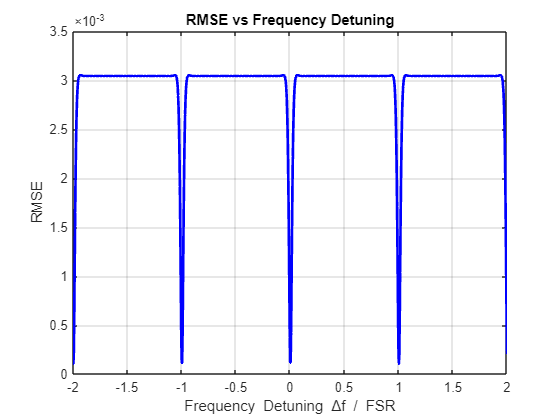


figure(402)
graph_drawer.plot_rmse(delta_f_array, rmse_det);

## Extension to N-th order

## LTI solver